# **ACM/IDS 104 - Problem Set 3 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

## **Problem 3 (10 points) The K-Means Algorithm for Clustering**

In this problem, we will be implementing the K-Means Algorithm for clustering vectors in $\mathbb{R}^2$. To start, let us load and visualize our dataset.

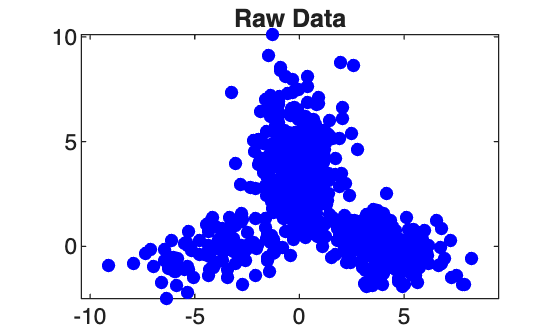

load clustering_data.mat
figure;
plot(x(:,1),x(:,2),'.b','MarkerSize',15);
title("Raw Data")
axis equal;

rng(2016); % for reproducibility

## **Part (a) The Algorithm**

In this part, we will implement the algorithm for $K=3$, which seems to be a reasonable number of clusters for this dataset. Show the clusters after the 1st, 5th, 10th and last iteration. This will illustrate the cluster evolution as the algorithm runs. $\texttt{subplot()}$ is very useful here.

To further aid our understanding of the algorithm, we will be keeping track of a few things:

- Keep track of the evolution of the representatives for each cluster. You can do so by updating the variable $\texttt{z}$ after each iteration.

- Keep track of the objective function value at each iteration.

Once you are done implementing the algorithm, feel free to change the value of $\texttt{K}$ and see how the clusterings are altered.

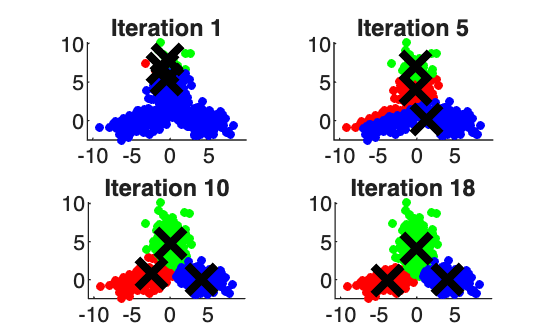

%{
Some useful setup done for you
%}
K = 3; % number of clusters
n = length(x); % number of vectors
c = zeros(n, 1); % clustering : c(i) is the cluster number for vector x(i, :)
iter = 0; % iteration number
z = datasample(x, K); % initial representatives

z_history = zeros(K, 2, 100);
z_history(:, :, 1) = z;
obj_func = zeros(100, 1);

%{
Step 1: Partitioning into clusters given our initial representatives
%}
for i = 1:n
    distances = zeros(K, 1);
    for k = 1:K
        distances(k) = norm(x(i,:) - z(k,:));
    end
    [~, c(i)] = min(distances);
end

%{
Increment the iteration number
Update the objective function
%}
iter = iter + 1;
obj_func(iter) = 0;
for i = 1:n
    obj_func(iter) = obj_func(iter) + norm(x(i,:) - z(c(i),:))^2;
end

c_at_iter = zeros(n, 4); % store c at 1, 5, 10, and final one
z_at_iter = zeros(K, 2, 4);
c_at_iter(:, 1) = c;
z_at_iter(:, :, 1) = z;

%{
Iterate until convergence:
%}
converged = false;
while ~converged
    % compute mean of each cluster
    z_old = z;
    for k = 1:K
        cluster_points = x(c == k, :);
        if ~isempty(cluster_points)
            z(k, :) = mean(cluster_points, 1);
        end
    end
    
    % resssign to nearest representative
    for i = 1:n
        distances = zeros(K, 1);
        for k = 1:K
            distances(k) = norm(x(i,:) - z(k,:));
        end
        [~, c(i)] = min(distances);
    end
    iter = iter + 1;
    z_history(:, :, iter) = z;
    obj_func(iter) = 0;
    for i = 1:n
        obj_func(iter) = obj_func(iter) + norm(x(i,:) - z(c(i),:))^2;
    end
    
    % store at specific iterations
    if iter == 5
        c_at_iter(:, 2) = c;
        z_at_iter(:, :, 2) = z;
    elseif iter == 10
        c_at_iter(:, 3) = c;
        z_at_iter(:, :, 3) = z;
    end
    
    % check convergence
    if norm(z - z_old) < 1e-6 || iter > 100
        converged = true;
        c_at_iter(:, 4) = c;
        z_at_iter(:, :, 4) = z;
    end
end

z_history = z_history(:, :, 1:iter);
obj_func = obj_func(1:iter);

%{
Plotting
%}
figure;
colors = ['r', 'g', 'b'];
iterations_to_show = [1, 5, 10, iter];

for idx = 1:4
    subplot(2, 2, idx);
    hold on;  
    for k = 1:K
        cluster_idx = (c_at_iter(:, idx) == k);
        plot(x(cluster_idx, 1), x(cluster_idx, 2), '.', 'Color', colors(k), 'MarkerSize', 10);
    end
    plot(z_at_iter(:, 1, idx), z_at_iter(:, 2, idx), 'kx', 'MarkerSize', 15, 'LineWidth', 3);
    
    title(sprintf('Iteration %d', iterations_to_show(idx)));
    axis equal;

    hold off;
end

## **Part (b) Evolution of Representatives**

Now, let us see the dynamics of the representatives. Plot the original (raw) data and the trajectories of the cluster representatives in one figure. $\texttt{squeeze()}$ might be useful here.

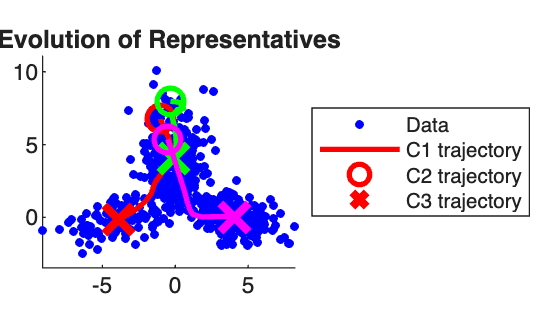

figure;
hold on;

plot(x(:,1), x(:,2), '.b', 'MarkerSize', 10);
colors = ['r', 'g', 'm'];
for k = 1:K
    trajectory = squeeze(z_history(k, :, :));
    plot(trajectory(1, :),trajectory(2, :), '-', 'Color', colors(k), 'LineWidth', 2);
    plot(trajectory(1, 1),trajectory(2, 1), 'o', 'Color', colors(k), 'MarkerSize', 10, 'LineWidth', 2);
    plot(trajectory(1, end),trajectory(2, end), 'x', 'Color', colors(k), 'MarkerSize', 15, 'LineWidth', 3);
end

title('Evolution of Representatives');
legend('Data', 'C1 trajectory', 'C2 trajectory', 'C3 trajectory', 'Location', 'eastoutside'); % key was overlapping so I moved it to side
axis equal;
hold off;

## **Part (c) Objective Function**

Plot the values of the objective function against the iteration number. Does the trend match what we expect? Report the minimum value of the objective function using $\texttt{disp()}$.

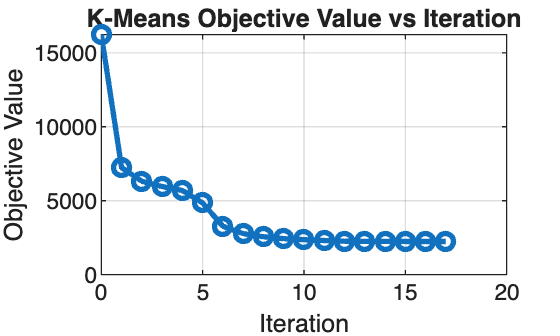

figure;
plot(0:iter-1, obj_func(1:iter), '-o', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Objective Value');
title('K-Means Objective Value vs Iteration');
grid on;

disp('Minimum value of objective function:');

Minimum value of objective function:


disp(min(obj_func(1:iter)));

   2.2452e+03



## **Part (d) Comparing with **$\texttt{kmeans()}$

The K-means algorithm is a very popular clustering algorithm and it is often used in various applications. As such, it is implemented in most numerical software packages. In MATLAB, it exists as the built-in function $\texttt{kmeans()}$. In the simplest form, $\texttt{idx = kmeans(X, k)}$ performs K-means clustering to partition the rows in the data matrix $\texttt{X}$ into $\texttt{k}$ clusters, and returns a vector $\texttt{idx}$ containing cluster indices for each row. To compare your implementation with the built-in one, plot the clustering your obtained in (a) and the clustering obtained by using $\texttt{kmeans()}$.

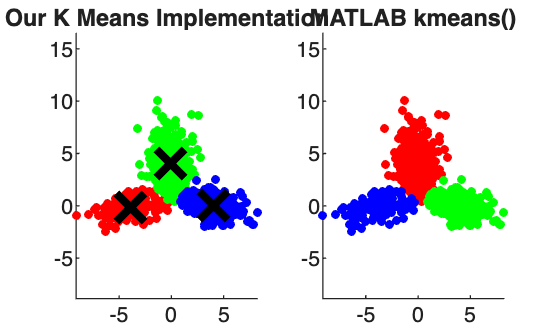

rng(2016); % for reproducibility
idx_builtin = kmeans(x, K);

figure;

% Our Implementation
subplot(1, 2, 1);
hold on;
colors = ['r','g','b'];
for k = 1:K
    cluster_idx = (c == k);
    plot(x(cluster_idx, 1), x(cluster_idx, 2), '.', 'Color', colors(k), 'MarkerSize', 10);
end
plot(z(:, 1), z(:, 2), 'kx', 'MarkerSize', 15, 'LineWidth', 3);
title('Our K Means Implementation');
axis equal;
hold off;

% built-in kmeans
subplot(1, 2, 2);
hold on;
for k = 1:K
    cluster_idx = (idx_builtin == k);
    plot(x(cluster_idx, 1), x(cluster_idx, 2), '.', 'Color', colors(k), 'MarkerSize', 10);
end
title('MATLAB kmeans()');
axis equal;
hold off;

## **Problem 5 (10 points) Gram Matrices for Text Classification**

Gram matrices are used in many different applications. Here is a simple example of application to classification of text documents. Suppose we have a collection of $n$ text documents and we want to measure similarity between them. First, we predefine a list of words (the "dictionary'') $w_1,w_2,w_3,\cdots , w_m$ appearing in the documents. Then, for each text $i$ we construct a vector $x_i\in\mathbb{R}^m$ whose $j^{\text{th}}$ component is the number of times the word $w_j$ appears in the text. This way, each text is represented as a vector in $\mathbb{R}^m$. This representation is often referred to as the "bag of words" representation. 

Let $\langle\cdot,\cdot\rangle$ be the usual dot product in $\mathbb{R}^m$ and $\|\cdot\|$ be the Euclidean norm. Let us normalize all vectors $z_i = \frac{x_i}{\|x_i\|}$ and define:


$$Z = [z_1\cdots z_n]\in\mathbb{M}_{m\times n}$$


Let $G$ be the Gram matrix associated with $z_1\cdots z_n$:


$$G = Z^TZ\in \mathbb{M}_{n\times n}$$


Since all $z_i$ are unit vectors:


$$G_{ij}=z_i^Tz_j=\|z_i\|\|z_j\|\cos\theta_{ij}=\cos\theta_{ij}$$


where $\theta_{ij}$is the angle between $z_i$ and $z_j$, which of course is the same as the angle between $x_i$ and $x_j$. This is widely use as a *measure of similarity* between documents. Hence, the more similar two texts $i$ and $j$ are, the closer $G_{ij}$ is to 1.

Now, let us apply this method to real texts. The task is to compare the text of the US Constitution ([found here](https://www.constituteproject.org/constitution/United_States_of_America_1992)) with the Wikipedia pages of Bernie Sanders, Hillary Clinton, Donald Trump, Ted Cruz, and John Kasich, and to find the page which is "closest" to the Constitution.

## Part (a) Setup

To start, we will define a list of $m=10$ words. To find the most "relevant words", copy the text of the Constitution and paste it into a word-cloud generator ([such as this one](http://worditout.com/word-cloud/make-a-new-one)). High frequency words appear large and we can form the dictionary from these words. Note that common sense is needed: words like "amendment'' and "section'' would appear large, but it makes no sense to include them into the dictionary. Also, it makes sense to include "United States'' as a single "word'', not two separate words, etc. But you are free to chose your own dictionary. In the code box below, please fill out the dictionary with your chosen words.

%{
DICTIONARY:
1) States
2) President
3) United
4) State
5) any
6) Congress
7) Section
8) all
9) Law
10) Office
%}

## Part (b) Fun

With your specified dictionary, let us see which Wikipedia page is closest. First, construct $n=6$ vectors (as specified above), one for each Wikipedia page and one for the Constitution. No need to get fancy here; just go to the related page and search for the number of occureneces of the words in your dictionary. Put all your results in a column vector for each candidate:

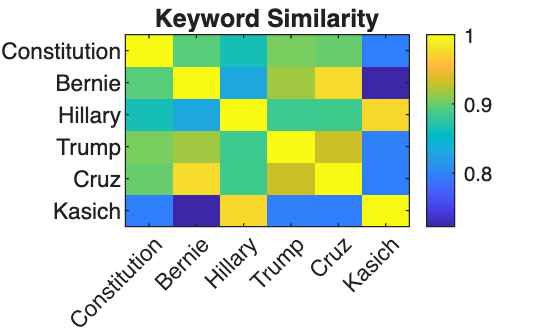

%{
Report your results here
%}
% I used a python BeautifulSoup script to fetch these given the urls
% see bottom of document
constitution = [128; 120; 85; 80; 78; 64; 55; 42; 39; 37];
bernie = [102; 53; 101; 34; 15; 47; 1; 33; 23; 29];
hillary = [78; 75; 76; 126; 13; 19; 1; 19; 35; 27];
trump = [89; 109; 92; 53; 16; 24; 1; 29; 50; 67];
cruz = [92; 50; 81; 44; 10; 35; 0; 21; 46; 19];
kasich = [38; 40; 28; 89; 5; 15; 0; 18; 25; 15];

%{
Normalize your vectors
%}
X = [constitution, bernie, hillary, trump, cruz, kasich];
Z = zeros(size(X));
for i = 1:size(X, 2)
    Z(:, i) = X(:, i) / norm(X(:, i));

end

%{
Construct the Gram matrix G as discussed
%}
G = Z' * Z;

%{
You can visualize G by uncommenting the following lines of code
%}

Similarity scores with the Constitution:


figure;
imagesc(G);
colorbar;

Bernie: 0.8944
Hillary: 0.86287
Trump: 0.905
Cruz: 0.90008
Kasich: 0.79609


title('Keyword Similarity');
labels = {'Constitution', 'Bernie', 'Hillary', 'Trump', 'Cruz', 'Kasich'};

set(gca, 'XTick', 1:6, 'XTickLabel', labels, 'YTick', 1:6, 'YTickLabel', labels);

The Wikipedia page closest to the Constitution is: Trump


xtickangle(45);

Similarity score: 0.905



%{
Find the page closest to the Constitution text and report your
answer using disp()
%}
similarities = G(1, 2:end);
[max_similarity, max_idx] = max(similarities);
pages = {'Bernie', 'Hillary', 'Trump', 'Cruz', 'Kasich'};

disp('Similarity scores with the Constitution:');
for i = 1:length(pages)
    disp([pages{i}, ': ', num2str(similarities(i))]);
end

disp(' ');
disp(['The Wikipedia page closest to the Constitution is: ', pages{max_idx}]);
disp(['Similarity score: ', num2str(max_similarity)]);

%{
# Web Parser Keyword Script
import requests
from bs4 import BeautifulSoup
from collections import Counter
import re

target_words = ["States", "President", "United", "State", "any", "Congress", "Section", "all", "Law", "Office"]

def count_words(url):
    # server blocks automated scripts so we use spoofing
    headers = {
        "User-Agent": (
            "Mozilla/5.0 (Macintosh; Intel Mac OS X 10_15_7) "
            "AppleWebKit/537.36 (KHTML, like Gecko) "
            "Chrome/118.0.0.0 Safari/537.36"
        )
    }
    try:
        response = requests.get(url, headers=headers)
        response.raise_for_status()
        soup = BeautifulSoup(response.text, 'html.parser')
        text = soup.get_text(separator=' ')
        words = re.findall(r'\b\w+\b', text.lower())
        counts = Counter(words)
        return [counts[word.lower()] for word in target_words]
    except requests.RequestException as e:
        print(f"Error fetching {url}: {e}")
        return [0] * len(target_words)

if __name__ == "__main__":
    urls = []
    print("Gimme urls:")
    for i in range(6):
        urls.append(input(f"URL {i+1}: ").strip())

    print("\nResults:\n")
    labels = ['a', 'b', 'c', 'd', 'e', 'f']
    for label, url in zip(labels, urls):
        counts = count_words(url)
        formatted = "; ".join(map(str, counts))
        print(f"{label} = [{formatted}];")
%}

Submit the obtained result to the corresponding piazza poll. Remember: this is not about your political preferences, it is about your data analysis :)